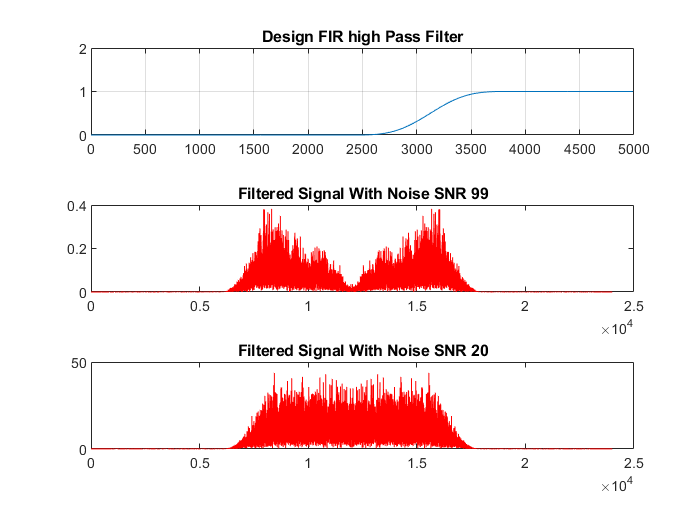

F1=8000;
F2=3000;
F3=2000;
r1=2;
r2=60;
p=1-10.^(-r1/20);
s=10.^(-r2/20);
FF=[F3 F2];
ma=[1 0];
v=[p s];
[A23,wA23,bt,Yp]=kaiserord(FF,ma,v,F1);
highpassfilter=fir1(A23,wA23,'high',kaiser(A23+1,bt));
[h,w]=freqz(highpassfilter,1);
figure(5);
subplot(311)
plot(w*10000*0.5/pi,abs(h));
title('Design FIR high Pass Filter','fontweight','bold');
grid;
Signal_3=fftfilt(highpassfilter,with_noise1);
sound(Signal_3,F1);
sound(Signal_3);
Signal3=fft(Signal_3);
subplot(312)
plot(abs(Signal3),'r');
title('Filtered Signal With Noise SNR 99');
Signal_4=fftfilt(highpassfilter,with_noise2);
sound(Signal_4,F1);
sound(Signal_4);
signal4=fft(Signal_4);
subplot(313)
plot(abs(signal4),'r');
title('Filtered Signal With Noise SNR 20');

subplot(3,1,1)
xlim([0 5000])
ylim([0.00 2.00])